% Load your data
% Assuming you have your input data in 'inputs' and output data in 'targets'
% inputs should be a matrix of size [19, numSamples]
% targets should be a matrix of size [11, numSamples]

D = readtable("DataDeepNN.txt")

D = 20529×31 table
         timestamps         T_amb_avg_last_3hours    T_amb_avg_following_24hours    Q_heating_last_3hours    Q_heating_following_24hours    Q_solar_last_3hours    Q_solar_following_24hours    Q_internal_last_3hours    Q_internal_following_24hours    EG_LivingKitchen_degC    EG_HallwayEntrance_degC    EG_Utilities_degC    EG_Dressing_degC    EG_Sleeping_degC    EG_Bath_degC    EG_GuestBath_degC    EG_Server_degC    OG_Office_degC    OG_Sleeping_degC    OG_Bath_degC    EG_LivingKitchen_degC_24hours    EG_HallwayEntrance_degC_24hours    EG_Utilities_degC_24hours    EG_Dressing_d


inputs = D{:,2:20}

inputs =     0.6433    0.6718         0         0         0    3.3925    0.4068    4.1076    0.7088    0.7390    0.7301    0.7242    0.7305    0.7240    0.7379    0.7620    0.7180    0.7122    0.7323
    0.6426    0.6718         0         0         0    3.3925    0.3997    4.1076    0.7084    0.7394    0.7301    0.7241    0.7305    0.7241    0.7381    0.7620    0.7180    0.7123    0.7322
    0.6419    0.6718         0         0         0    3.3925    0.3914    4.1065    0.7082    0.7394    0.7302    0.7241    0.7305    0.7239    0.7378    0.7620    0.7180    0.7124    0.7322
    0.6415    0.6717         0         0         0    3.3925    0.3851    4.1079    0.7086    0.7400    0.7300    0.7243    0.7308    0.7240    0.7379    0.7620    0.7178    0.7123    0.7321
    0.6412    0.6717         0         0         0    3.3925    0.3252    4.1080    0.7086    0.7398    0.7300    0.7241    0.7309    0.7239    0.7377    0.7620    0.7178    0.7127    0.7320
    0.6412    0.6717         0      


targets = D{:,21:31}

targets =     0.7012    0.7330    0.7278    0.7232    0.7316    0.7240    0.7359    0.7620    0.7193    0.7135    0.7347
    0.7016    0.7334    0.7279    0.7229    0.7317    0.7237    0.7359    0.7620    0.7189    0.7136    0.7345
    0.7018    0.7334    0.7280    0.7229    0.7313    0.7237    0.7359    0.7620    0.7187    0.7135    0.7345
    0.7020    0.7338    0.7281    0.7231    0.7311    0.7237    0.7359    0.7620    0.7191    0.7135    0.7345
    0.7023    0.7338    0.7279    0.7232    0.7309    0.7236    0.7355    0.7620    0.7189    0.7135    0.7343
    0.7025    0.7338    0.7281    0.7231    0.7309    0.7236    0.7357    0.7620    0.7186    0.7133    0.7341
    0.7027    0.7340    0.7281    0.7229    0.7307    0.7237    0.7359    0.7620    0.7186    0.7133    0.7340
    0.7028    0.7342    0.7283    0.7229    0.7307    0.7234    0.7357    0.7620    0.7187    0.7134    0.7341
    0.7033    0.7340    0.7281    0.7229    0.7305    0.7233    0.7355    0.7620    0.7185    0.7133  



sIv1 = datetime('01-Sep-2023 00:15:00');
eIv1 = datetime('15-Sep-2023 00:00:00');
sIv2 = datetime('29-Sep-2023 00:15:00');
eIv2 = datetime('13-Oct-2023 00:00:00');
sIv3 = datetime('27-Oct-2023 00:15:00');
eIv3 = datetime('17-Nov-2023 09:15:00');
sIv4 = datetime('15-Dec-2023 00:15:00');
eIv4 = datetime('29-Dec-2023 00:00:00');
sIv5 = datetime('12-Jan-2024 00:15:00');
eIv5 = datetime('26-Jan-2024 00:00:00');
sIv6 = datetime('09-Feb-2024 00:15:00');
eIv6 = datetime('21-Feb-2024 11:45:00');
sIv7 = datetime('08-Mar-2024 00:15:00');
eIv7 = datetime('22-Mar-2024 00:00:00');
sIv8 = datetime('05-Apr-2024 00:15:00');
eIv8 = datetime('19-Apr-2024 00:00:00');

                trainInd = [find(D.timestamps >= sIv1 & D.timestamps <= eIv1) 
                            find(D.timestamps >= sIv2 & D.timestamps <= eIv2)
                            find(D.timestamps >= sIv3 & D.timestamps <= eIv3)
                            find(D.timestamps >= sIv4 & D.timestamps <= eIv4)
                            find(D.timestamps >= sIv5 & D.timestamps <= eIv5)
                            find(D.timestamps >= sIv6 & D.timestamps <= eIv6)
                            find(D.timestamps >= sIv7 & D.timestamps <= eIv7)
                            find(D.timestamps >= sIv8 & D.timestamps <= eIv8)]

trainInd =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



%Validierung

sIv1 = datetime('15-Sep-2023 00:15:00');
eIv1 = datetime('22-Sep-2023 00:00:00');
sIv2 = datetime('13-Oct-2023 00:15:00');
eIv2 = datetime('20-Oct-2023 00:00:00');
sIv3 = datetime('01-Dec-2023 12:15:00');
eIv3 = datetime('08-Dec-2023 00:00:00');
sIv4 = datetime('29-Dec-2023 00:15:00');
eIv4 = datetime('05-Jan-2024 00:00:00');
sIv5 = datetime('26-Jan-2024 00:15:00');
eIv5 = datetime('02-Feb-2024 00:00:00');
sIv6 = datetime('23-Feb-2024 12:15:00');
eIv6 = datetime('28-Feb-2024 23:45:00');
sIv7 = datetime('22-Mar-2024 00:15:00');
eIv7 = datetime('29-Mar-2024 00:00:00');
sIv8 = datetime('19-Apr-2024 00:15:00');
eIv8 = datetime('26-Apr-2024 00:00:00');

valInd =                    [find(D.timestamps >= sIv1 & D.timestamps <= eIv1) 
                            find(D.timestamps >= sIv2 & D.timestamps <= eIv2)
                            find(D.timestamps >= sIv3 & D.timestamps <= eIv3)
                            find(D.timestamps >= sIv4 & D.timestamps <= eIv4)
                            find(D.timestamps >= sIv5 & D.timestamps <= eIv5)
                            find(D.timestamps >= sIv6 & D.timestamps <= eIv6)
                            find(D.timestamps >= sIv7 & D.timestamps <= eIv7)
                            find(D.timestamps >= sIv8 & D.timestamps <= eIv8)]

valInd =         1345
        1346
        1347
        1348
        1349
        1350
        1351
        1352
        1353
        1354



%Test

sIv1 = datetime('22-Sep-2023 00:15:00');
eIv1 = datetime('29-Sep-2023 00:00:00');
sIv2 = datetime('20-Oct-2023 00:15:00');
eIv2 = datetime('27-Oct-2023 00:00:00');
sIv3 = datetime('08-Dec-2023 00:15:00');
eIv3 = datetime('15-Dec-2023 00:00:00');
sIv4 = datetime('05-Jan-2024 00:15:00');
eIv4 = datetime('12-Jan-2024 00:00:00');
sIv5 = datetime('02-Feb-2024 00:15:00');
eIv5 = datetime('09-Feb-2024 00:00:00');
sIv6 = datetime('01-Mar-2024 00:15:00');
eIv6 = datetime('08-Mar-2024 00:00:00');
sIv7 = datetime('29-Mar-2024 00:15:00');
eIv7 = datetime('05-Apr-2024 00:00:00');
sIv8 = datetime('26-Apr-2024 00:15:00');
eIv8 = datetime('28-Apr-2024 20:30:00');

                testInd =  [find(D.timestamps >= sIv1 & D.timestamps <= eIv1) 
                            find(D.timestamps >= sIv2 & D.timestamps <= eIv2)
                            find(D.timestamps >= sIv3 & D.timestamps <= eIv3)
                            find(D.timestamps >= sIv4 & D.timestamps <= eIv4)
                            find(D.timestamps >= sIv5 & D.timestamps <= eIv5)
                            find(D.timestamps >= sIv6 & D.timestamps <= eIv6)
                            find(D.timestamps >= sIv7 & D.timestamps <= eIv7)
                            find(D.timestamps >= sIv8 & D.timestamps <= eIv8)]

testInd =         2017
        2018
        2019
        2020
        2021
        2022
        2023
        2024
        2025
        2026




inputs = inputs'

inputs =     0.6433    0.6426    0.6419    0.6415    0.6412    0.6412    0.6413    0.6414    0.6416    0.6418    0.6421    0.6426    0.6427    0.6431    0.6434    0.6435    0.6436    0.6438    0.6443    0.6451    0.6457    0.6460    0.6469    0.6478    0.6483    0.6488    0.6497    0.6512    0.6529    0.6548    0.6571    0.6595    0.6616    0.6637    0.6657    0.6679    0.6706    0.6738    0.6768    0.6793    0.6818    0.6846    0.6868    0.6890    0.6913    0.6927    0.6931    0.6931    0.6933    0.6939
    0.6718    0.6718    0.6718    0.6717    0.6717    0.6717    0.6717    0.6717    0.6718    0.6718    0.6718    0.6718    0.6718    0.6718    0.6718    0.6719    0.6719    0.6720    0.6721    0.6722    0.6723    0.6724    0.6726    0.6727    0.6729    0.6731    0.6732    0.6734    0.6734    0.6735    0.6736    0.6736    0.6737    0.6739    0.6742    0.6744    0.6747    0.6750    0.6753    0.6756    0.6761    0.6766    0.6771    0.6775    0.6781    0.6787    0.6793    0.6800    0.6807

targets = targets' 

targets =     0.7012    0.7016    0.7018    0.7020    0.7023    0.7025    0.7027    0.7028    0.7033    0.7037    0.7036    0.7035    0.7037    0.7037    0.7037    0.7041    0.7046    0.7048    0.7050    0.7033    0.7018    0.7012    0.7008    0.7006    0.7001    0.6996    0.6995    0.6994    0.6998    0.6990    0.6989    0.6989    0.6992    0.7004    0.7011    0.7037    0.7076    0.7098    0.7102    0.7130    0.7130    0.7104    0.7094    0.7096    0.7108    0.7126    0.7140    0.7140    0.7144    0.7134
    0.7330    0.7334    0.7334    0.7338    0.7338    0.7338    0.7340    0.7342    0.7340    0.7344    0.7342    0.7346    0.7348    0.7344    0.7346    0.7352    0.7348    0.7348    0.7350    0.7348    0.7346    0.7346    0.7342    0.7340    0.7338    0.7338    0.7336    0.7332    0.7336    0.7336    0.7330    0.7328    0.7332    0.7336    0.7322    0.7322    0.7322    0.7322    0.7318    0.7314    0.7348    0.7362    0.7360    0.7350    0.7362    0.7366    0.7376    0.7370    0.737


% Define the network architecture
inputSize = 19;
hiddenLayerSize1 = 25; % Size of the first hidden layer
hiddenLayerSize2 = 20; % Size of the second hidden layer
outputSize = 11;

% Create a feedforward neural network
net = feedforwardnet([hiddenLayerSize1, hiddenLayerSize2]);

% Configure the neural network for training
net = configure(net, inputs, targets);

% Setup Division of Data for Training, Validation, Testing
net.divideFcn = 'divideind';  
net.divideMode = 'time';

net.divideParam.trainInd = trainInd;
net.divideParam.valInd = valInd;
net.divideParam.testInd = testInd;


% Set training parameters (optional)
net.trainParam.epochs = 1000; % Number of training epochs
net.trainParam.goal = 1e-6; % Performance goal

% Train the neural network
[net, tr] = train(net, inputs, targets);

MathWorks::System::IUserException in WebControllerFactory::create(): [Unrecognized method, property, or field 'ViewModel' for class 'handle'.

Error in matlab.ui.internal.componentframework.WebComponentController/getParentView (line 476)
            parentView = parentController.ViewModel;
                         ^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in 

MathWorks::System::IUserException in WebControllerFactory::create(): [Unrecognized method, property, or field 'ViewModel' for class 'handle'.

Error in matlab.ui.internal.componentframework.WebComponentController/getParentView (line 476)
            parentView = parentController.ViewModel;
                         ^^^^^^^^^^^^^^^^^^^^^^^^^^
Error in 


% View the network
view(net);


% Test the network
outputs = net(inputs);
errors = gsubtract(targets, outputs);
performance = perform(net, targets, outputs);

% Display performance
fprintf('Training performance: %f\n', performance);

Training performance: 0.000003


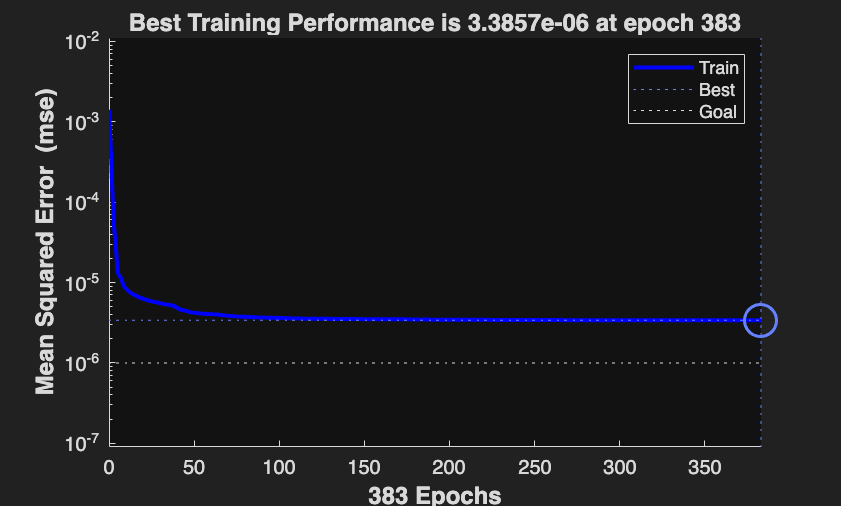


% Plot training performance
figure, plotperform(tr);


%Einfügen von Plots die berechnete Ergebnisse mit gemessenen vergleichen
% Compare computed outputs to measured ones
% Extract test outputs and targets
testOutputs = outputs(:, testInd);
testTargets = targets(:, testInd);

% Save the trained network
save('2_layer_network.mat', 'net');

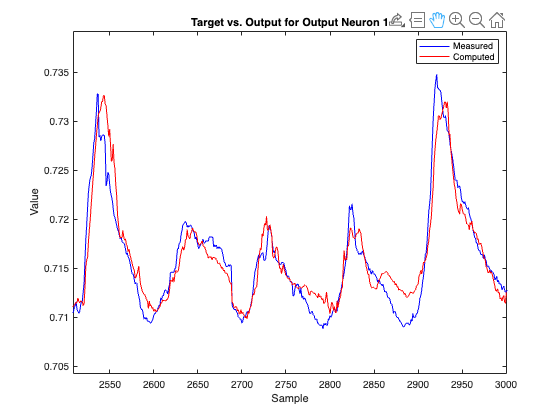

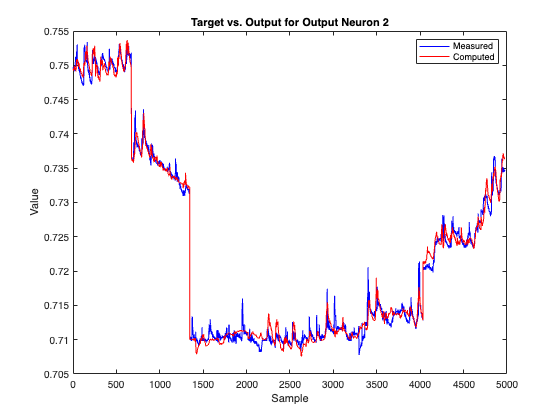

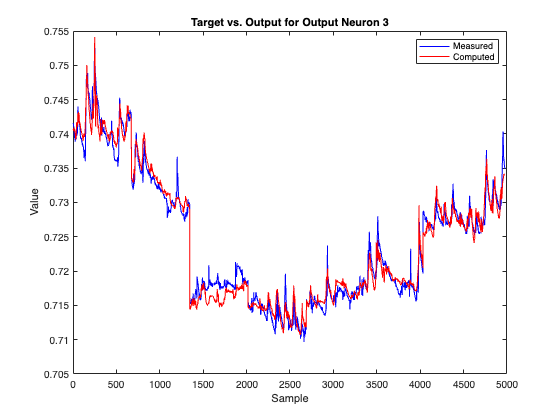

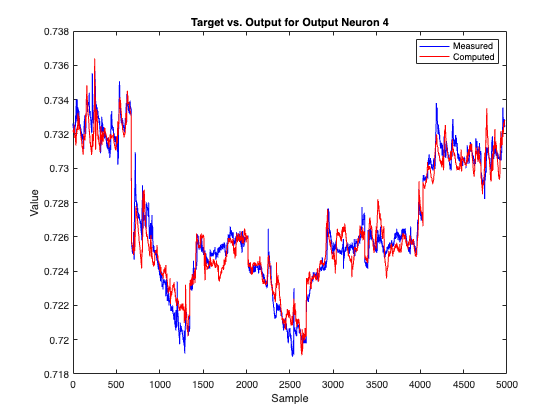

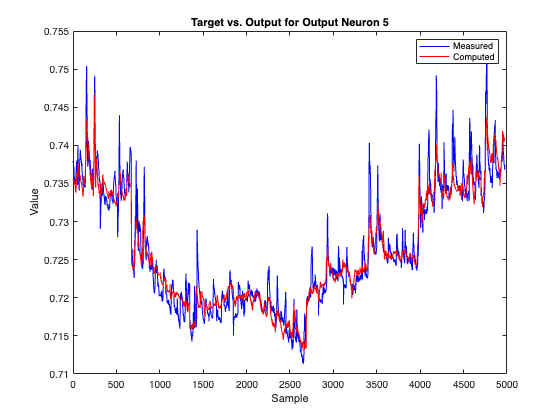

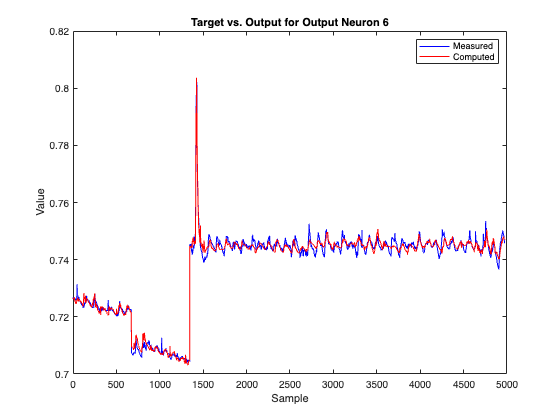

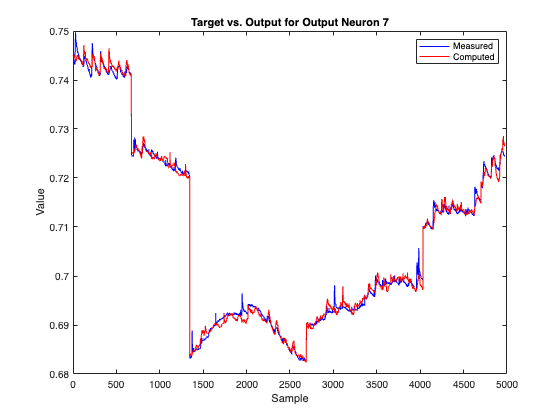

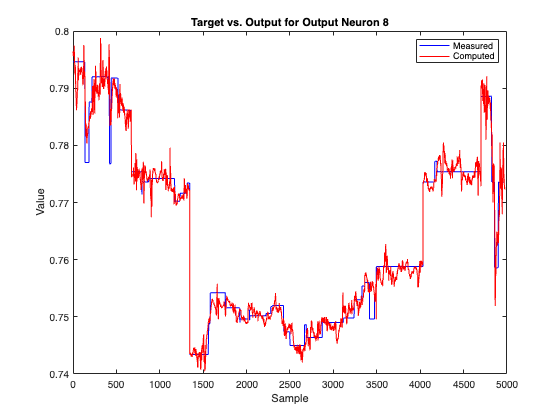


% Plot each target vs. output

for i = 1:size(testTargets, 1)
    figure;
    plot(testTargets(i, :), 'b');
    hold on;
    plot(testOutputs(i, :), 'r');
    hold off;
    title(['Target vs. Output for Output Neuron ', num2str(i)]);
    legend('Measured', 'Computed');
    xlabel('Sample');
    ylabel('Value');
end



%Computing time fürs Netz: 1:45 min